clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);
Template=double(imread('Template1.jpg'));
load('meanHistRGBTemplate.mat');

margen=501;%este es el tamaño de las ventanas que se van a usar, tiene que coincidir con el tamaño de las plantillas

tR=0.5;
tG=2;
tB=1;

se = strel('disk',100);

fr=5;%factor de reducción
margen=floor(501/fr/2);

%indices = find(T.quality == 4);

%for u = 1:height(T)
    k=2

k = 2


% Leer la imagen original
RGB = imread(string(fullfile(img_path, T{k,1})));

% Quito los artefactos que hay a veces
RGB_g=rgb2gray(RGB);
loNOnegro=RGB_g>10;
loNOnegro=imerode(loNOnegro, strel('disk',30));
loNOnegro=imdilate(loNOnegro, strel('disk',30));
RGB=double(RGB);
RGB=RGB.*loNOnegro;
RGB=uint8(RGB);

% Le paso un filtro para quitarle el ruido
RGB(:,:,1)=medfilt2(RGB(:,:,1),[3 3],"symmetric");
RGB(:,:,2)=medfilt2(RGB(:,:,2),[3 3],"symmetric");
RGB(:,:,3)=medfilt2(RGB(:,:,3),[3 3],"symmetric");

% Lo asemejo al histograma del template
RGB(:,:,1)=histeq(RGB(:,:,1),meanHistRGBTemplate(:,1));
RGB(:,:,2)=histeq(RGB(:,:,2),meanHistRGBTemplate(:,2));
RGB(:,:,3)=histeq(RGB(:,:,3),meanHistRGBTemplate(:,3));

% Guardo las dimensiones originales de la imagen
[alto_original, ancho_original, ~] = size(RGB);

% Redimensiono la imagen para que todas entren al for con las mismas
% dimensiones
RGB_redimensionada = imresize(RGB, [NaN, 3000], 'bicubic');
RGB_redimensionada = imresize(RGB_redimensionada, [NaN, 3000/fr], 'bicubic');

RGB_redimensionada_padded=double(padarray(RGB_redimensionada, [margen margen], 0));
[alto_redimensionada, ancho_redimensionada, ~] = size(RGB_redimensionada_padded);%en si creo que con lo anterior puedes sacar esto

TemplateRedimensioned = imresize(Template, [NaN, width(Template)/fr], 'bicubic');

% Creo las matrices que voy a conseguir en el siguiente for

correlacion_ponderada=zeros(alto_redimensionada-margen*2,ancho_redimensionada-margen*2);
diferencia=zeros(alto_redimensionada-margen*2,ancho_redimensionada-margen*2);
diferenciaRGB=zeros(alto_redimensionada-margen*2,ancho_redimensionada-margen*2,3);


for i=2 %Solo para el layer G
    for x=(margen+1):(ancho_redimensionada-margen)
        for y=(margen+1):(alto_redimensionada-margen)
            ventana=RGB_redimensionada_padded(y-margen:y+margen, x-margen:x+margen, i);
            resta_template=ventana-TemplateRedimensioned(:,:,i);
            resta_template=resta_template.^2;
            diferencia(y-margen,x-margen)=sum(resta_template(:));
        end
    end
   % diferenciaRGB(:,:,i)=diferencia;%En esta matriz guardo las matrices de diferencia obtenidas en el for para cada una de las capas de color
end

%correlacion=1/(1+diferenciaRGB);
%correlacion_ponderada = correlacion(:,:,1).*tR + correlacion(:,:,2).*tG + correlacion(:,:,3);

correlacion=1./(1+diferencia);

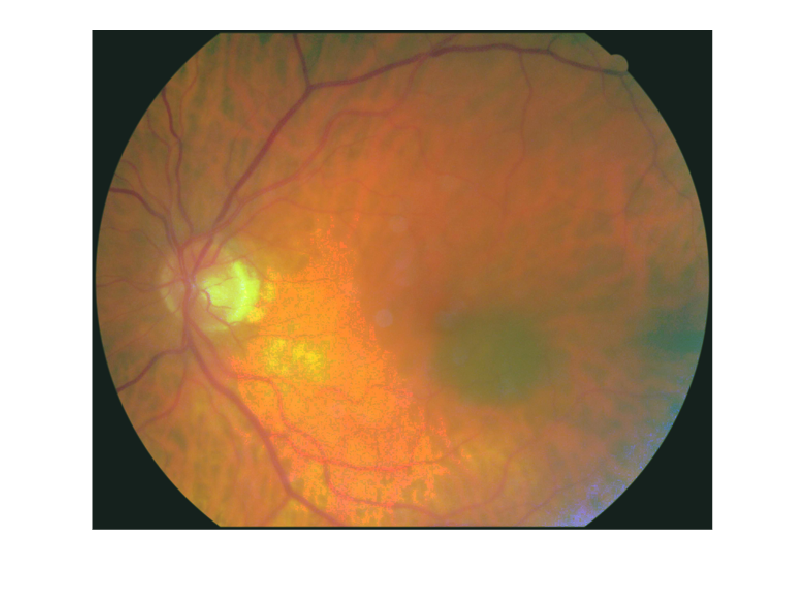

imshow(RGB_redimensionada)

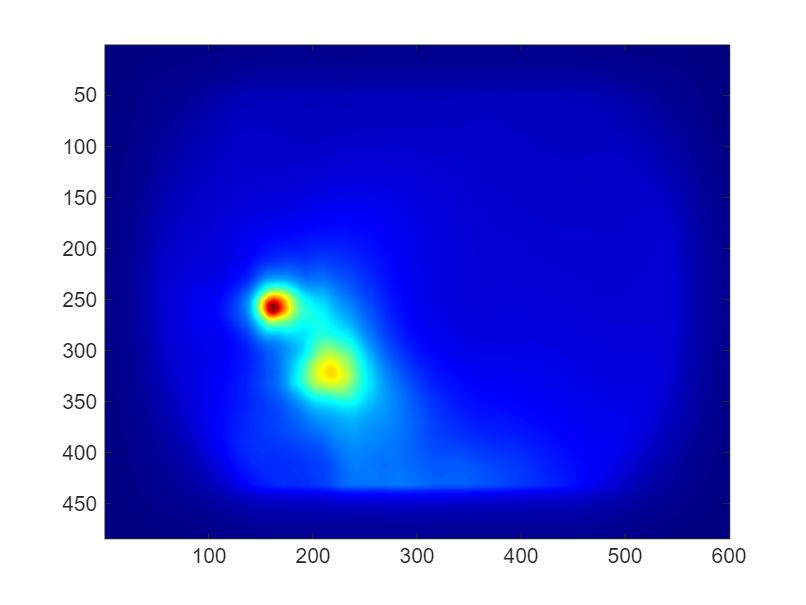

figure;
colormap 'jet';
imagesc(correlacion); 

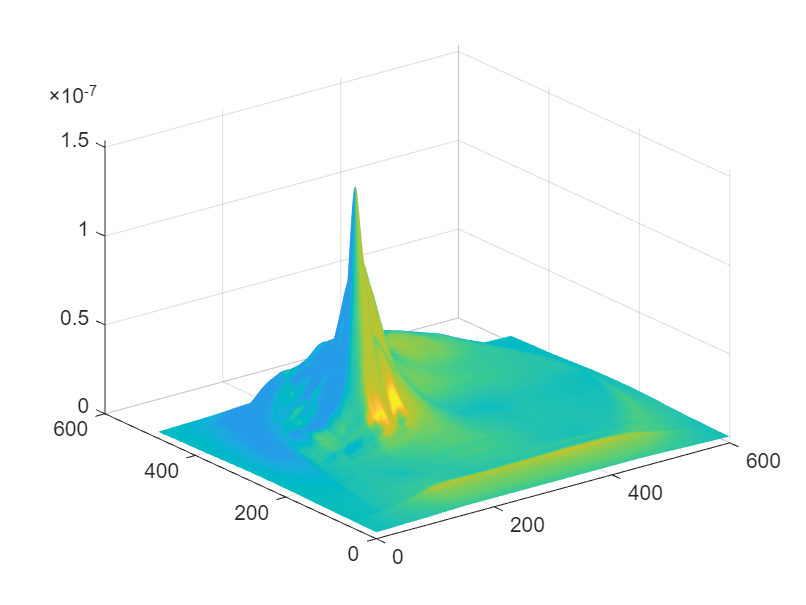

figure;
surfl(correlacion);
shading interp  

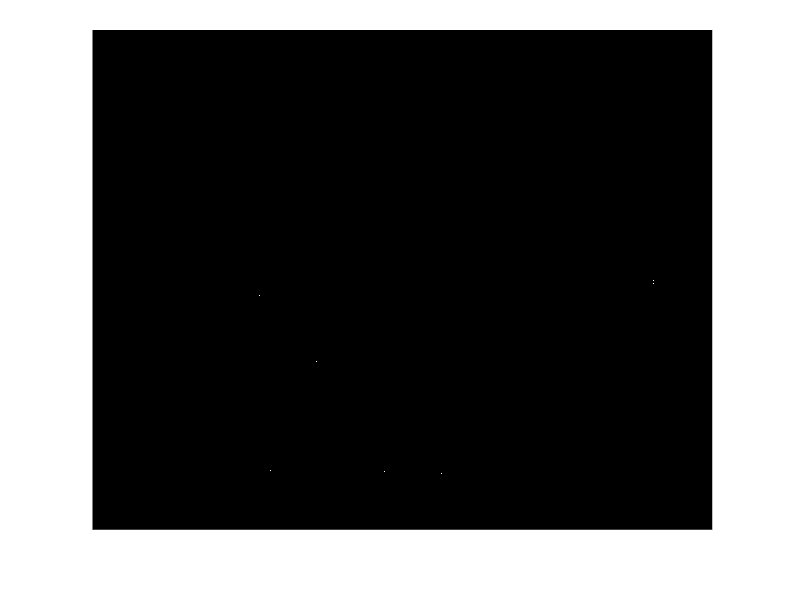

peaks = imregionalmax(correlacion,8);
imshow(peaks)

I=rgb2gray(RGB_redimensionada);
correlacion1=correlacion./max(correlacion(:));
max(correlacion1(:))

ans = 1

T=graythresh(correlacion1)

T = 0.1843

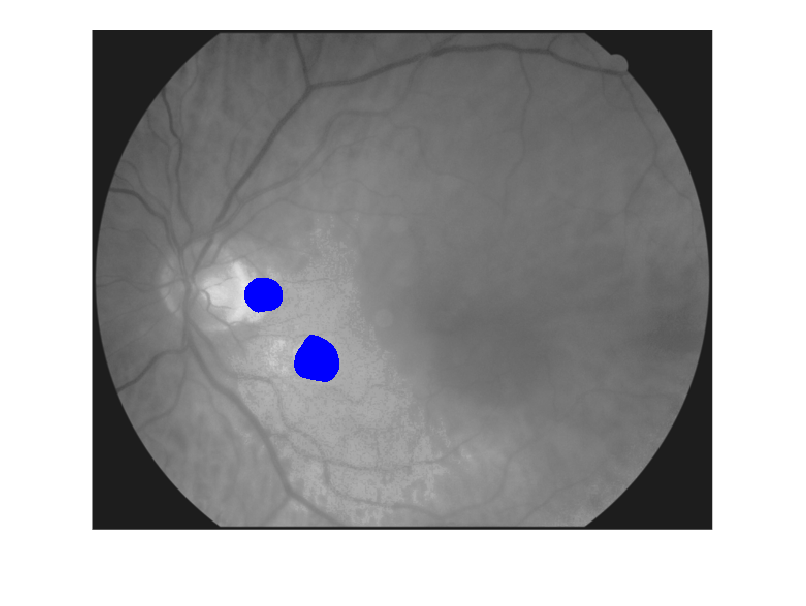

correlacion_Threshed=imbinarize(correlacion1,0.5);
brightest_region = imoverlay(I,correlacion_Threshed,'blue');
imshow(brightest_region)

%end

Encuentro caps

% Step 2: Convert to grayscale
grayImage = I;

% Step 3: Apply GLoG filter
filterSize = 100; % Adjust the filter size as needed
sigma = 2; % Adjust the sigma value as needed
filter = fspecial('log', filterSize, sigma);
grayImage = imresize(grayImage, [NaN, 600], 'bicubic');
filteredImage = imfilter(grayImage, filter, 'same');

% Step 4: Threshold the filtered image
threshold = 0.5; % Adjust the threshold value as needed
binaryImage = filteredImage > threshold;

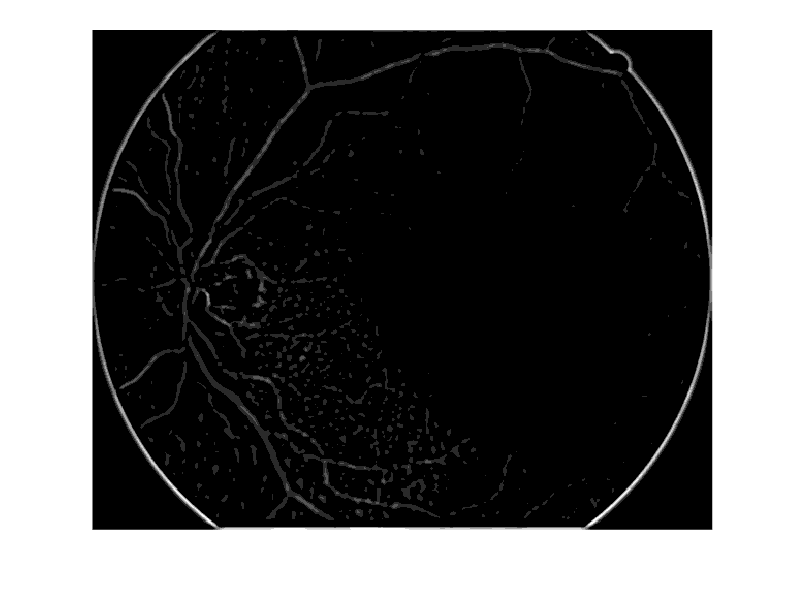

imshow(filteredImage,[])

max(filteredImage(:))

ans = uint8
6

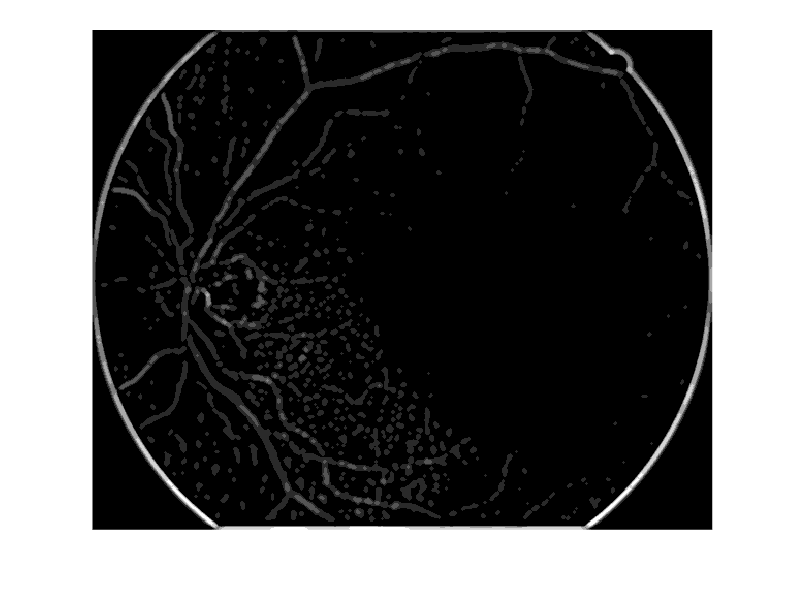

filteredImage=double(filteredImage);
filteredImage_d=imdilate(filteredImage,strel('disk',1));
imshow(filteredImage_d,[])

Prueba=filteredImage_d.*correlacion;

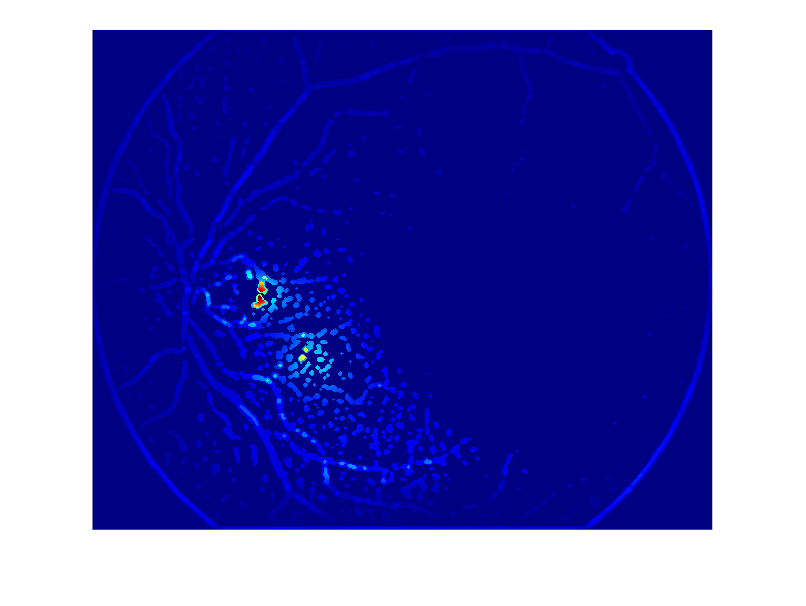

imshow(Prueba,[])
colormap 'jet';

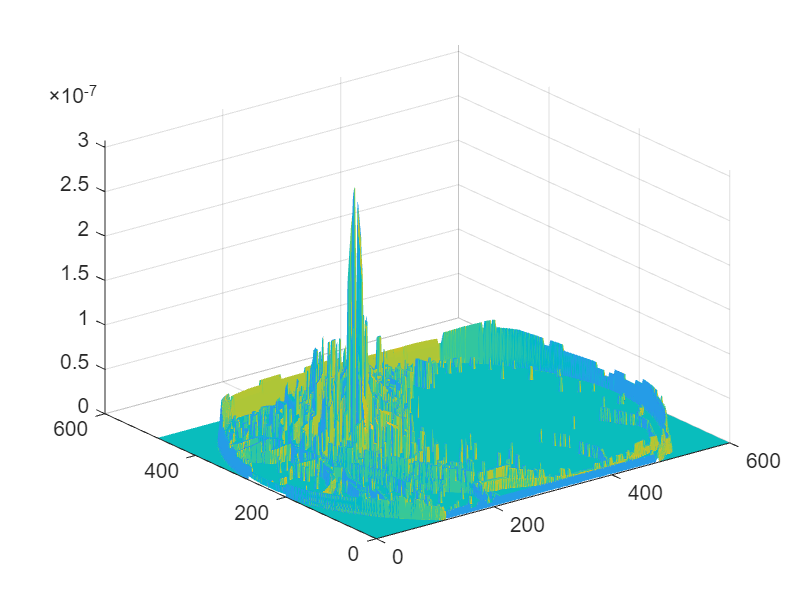

figure;
surfl(Prueba);
shading interp  

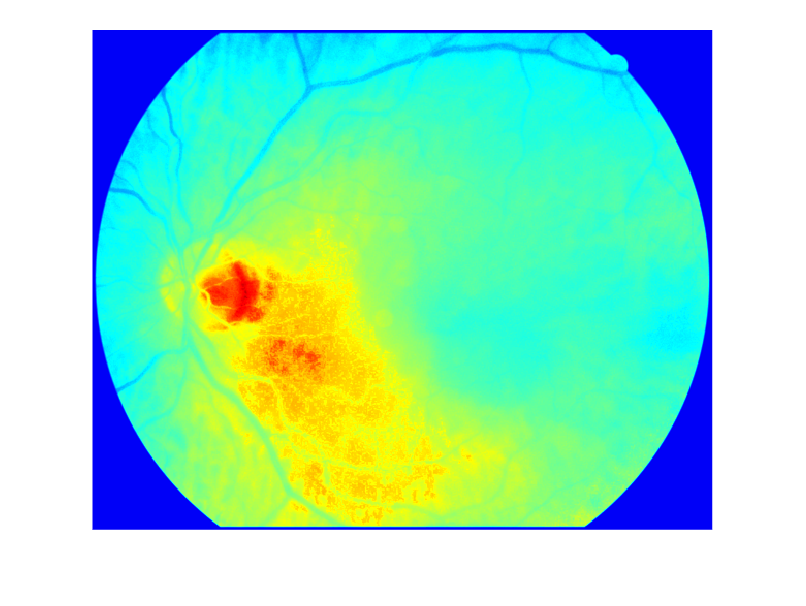

figure;
imshow(I);
%hold on;
colormap 'jet';

%h=imagesc(correlacion); 
%h.AlphaData=0.1
%hold off;